# Impedance Equivalent Circuit

maxFreq = 1e7; %Maximum frequency to test
minFreq = 1e0; %Minimum frequency to test
samplesPerSlice =1000; %Every order of magnitude will be divided 
                                              %into this many equal parts (for efficiency)

%Create the frequency vector (at higher frequencies increase the distance between points) 
%CAN DO ALL THIS WITH logspace(a,b,n) function
logMin = log10(minFreq);
logMax = log10(maxFreq);
slices = (logMax-logMin); %Slice every order of magnitude in equal chunks
samples = slices*samplesPerSlice;
freq = zeros([1 samples]); %create the vector, the frequencies are wrong
for slice = 1:(logMax-logMin) %Set the right frequencies in the vector
    freqsSlice = linspace(minFreq*(10^(slice-1)),minFreq*(10^(slice)),samplesPerSlice);
    freq((slice-1)*samplesPerSlice+1:(slice)*samplesPerSlice) = freqsSlice;
end

Z = zeros([1 samples]);

%Create the circuit to analyse
Rg = Resistor(6.68e7);
Cg = Capacitor(3.38e-11);
Rgb = Resistor(2.96e4);
Cgb = Capacitor(5.58e-12);
%https://pubs.rsc.org/en/content/articlehtml/2018/ra/c7ra13261a
%Values used in this test

for sample = 1:samples
    Z1 = SumImpedances('parallel',freq(sample),Rg,Cg);
    Z2 = SumImpedances('parallel',freq(sample),Rgb,Cgb);
    Z(sample) = Z1+Z2;
end

### Plot Data

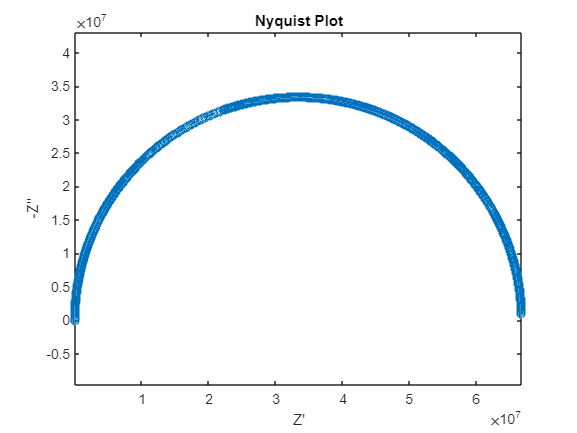

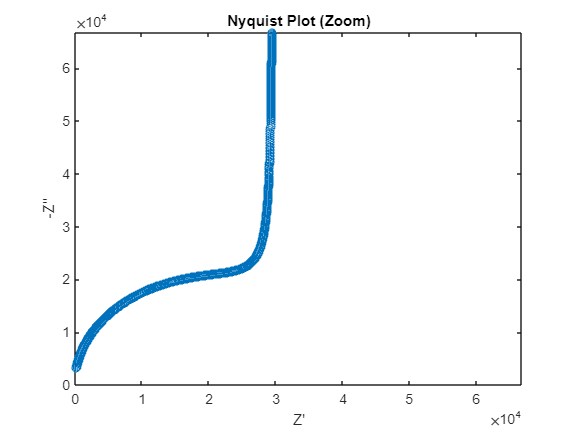

%Nyquist plot
Nyquist(Z,1,1);

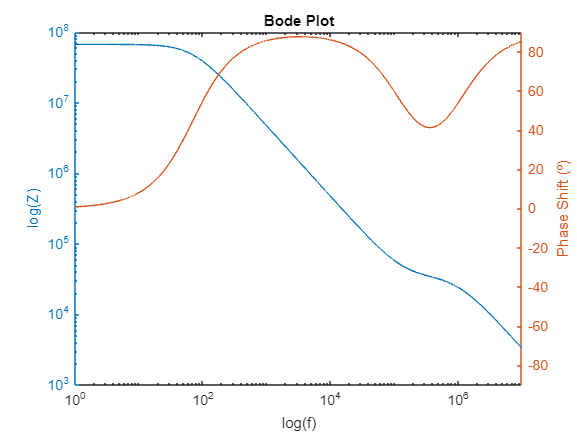


%Bode plot
Bode(freq,Z);

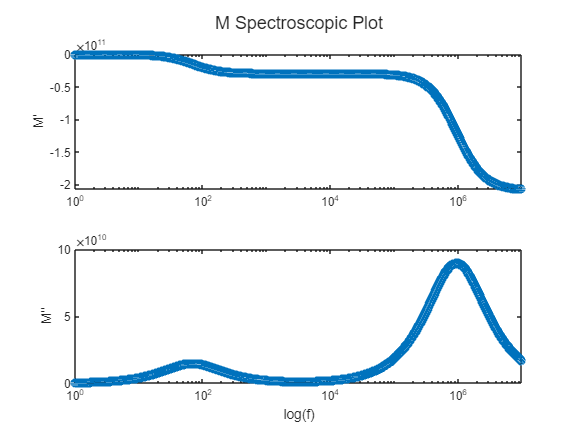

startingPoints =         1e-11        1e-11        1e+05        1e+05


ans =      General model:
     ans(x) = real(((1/R1)+1i*2*pi*x*C1)^-1+((1/R2)+1i*2*pi*x*C2)^-1)
     Coefficients (with 95% confidence bounds):
       C1 =       1e-11  (-4.954e+08, 4.954e+08)
       C2 =       1e-11  (-4.954e+08, 4.954e+08)
       R1 =       1e+05  (-3.957e+21, 3.957e+21)
       R2 =       1e+05  (-3.957e+21, 3.957e+21)

c =   Circuit with properties:

     Components: {{1×3 cell}  {1×3 cell}}
    Connections: [2×2 double]


ans =   graph with properties:

    Edges: [1×2 table]
    Nodes: [2×0 table]


ans =      0



%M Spectroscpoic plot
[~,~,~,~,areaMimag] = MSpectroscopic(freq,Z,ones([1 samples]));

**Functions**

function varargout = Nyquist(Z,equalAxis,zoomPlot,xMax,yMax) 
    arguments
        Z {mustBeNumeric}
        equalAxis = 0;
        zoomPlot = 0;
        xMax = max(real(Z))/1000;
        yMax = max(real(Z))/1000; %Default values for zommed axis
    end

    figure;
    plot(real(Z),-imag(Z),'o--');
    ylabel("-Z''");
    xlabel("Z'");
    title("Nyquist Plot");
    if equalAxis
        axis equal;
    end

    if zoomPlot
        figure;
        plot(real(Z),-imag(Z),'o--');
        ylabel("-Z''");
        xlabel("Z'");
        title("Nyquist Plot (Zoom)");
        xlim([0 xMax]);
        ylim([0 yMax]);
    end

    if nargout == 1
        varargout{1} = max(-imag(Z));
    end
end

function varargout = Bode(Frange,Z)
    arguments
        Frange {mustBeNumeric} 
        Z {mustBeNumeric,mustBeEqualSize(Frange,Z)}
    end

    figure;
    yyaxis left;
    loglog(Frange,abs(Z));
    xlim([Frange(1) Frange(end)]);
    ylabel("log(Z)");
    yyaxis right;
    semilogx(Frange,-angle(Z)*(180/pi)); %-1 is multyplying angle shift 
                                                  % because I think the phase shift is taken from 
                                                  % Z=Zreal-iZimg
    ylim([-90 90]);
    ylabel("Phase Shift (º)");
    xlabel("log(f)");
    xlim([Frange(1) Frange(end)]);
    title("Bode Plot");

    if nargout == 1
        varargout{1} = range(-angle(Z)*(180/pi));
    end
end

function varargout = MSpectroscopic(Frange,Z,C) %demanar si vol afegir valors de cada pic al graf, variable d'entrada opcional
    arguments
        Frange {mustBeNumeric} 
        Z {mustBeNumeric,mustBeEqualSize(Frange,Z)}
        C {mustBeNumeric,mustBeEqualSize(C,Frange)} %Capacitance (as a vector in case it changes with frequency)
    end

    Zreal = real(Z);
    Zimag = imag(Z);
    w = 2*pi*Frange;

    Mreal = w.*Zimag.*C;
    Mimag = w.*Zreal.*C;

    [pR,iR,wR,promR] = findpeaks(Mreal);
    [pI,iI,wI,promI] = findpeaks(Mimag);
    fR = Frange(iR);
    fI = Frange(iI);

    figure;
    t = tiledlayout(2,1);
    n = nexttile;
    semilogx(Frange,Mreal,'o--');
    xlim([Frange(1) Frange(end)]);
    ylabel(n,"M'");
    n = nexttile;
    semilogx(Frange,Mimag,'o--');
    ylabel(n,"M''");
    xlabel("log(f)");
    xlim([Frange(1) Frange(end)]);
    title(t,"M Spectroscopic Plot");

    if nargout == 1
        varargout{1} = [Mreal',Mimag'];
    elseif nargout == 3        
        if isempty(pR) 
            pR = Inf;
            fR = Inf;
        end
        if isempty(pI) 
            pI = Inf;
            fI = Inf;
        end

        varargout{1} = [Mreal',Mimag'];
        varargout{2} = [pR,fR];
        varargout{3} = [pI,fI];
    elseif nargout == 5
        if isempty(pR) 
            pR = -Inf;
            fR = -Inf;
        end
        if isempty(pI) 
            pI = -Inf;
            fI = -Inf;
        end

        %calculate area under peaks
        aRPeaks = wR.*promR;
        aIPeaks = wI.*promI;

        if isempty(aRPeaks) 
            aRPeaks = -Inf;
        end
        if isempty(aIPeaks) 
            aIPeaks = -Inf;
        end

        varargout{1} = [Mreal',Mimag'];
        varargout{2} = [pR,fR];
        varargout{3} = [pI,fI];
        varargout{4} = aRPeaks; %Using prominence*half-width
        varargout{5} = aIPeaks; %Using prominence*half-width
    end
end

function mustBeEqualSize(a,b)
    %Test for equal size
    if ~isequal(size(a),size(b))
        eid = 'Size:notEqual';
        msg = 'Size of inputs must be equal.';
        throwAsCaller(MException(eid,msg));
    end
end